# Generación de un mapa de ocupación tridimensional aleatorio para la planificación de un UAV

En este ejemplo se muestra cómo generar un mapa de ocupación tridimensional aleatorio añadiendo cierta cantidad de obstáculos de dimensiones variables en posiciones aleatorias en el mapa. La intención es utilizar el mapa generado para la planificación de la trayectoria utilizando algoritmos como RRT, RRT* y Hybrid A*.

Fuente: https://es.mathworks.com/help/uav/ug/motion-planning-with-rrt-for-fixed-wing-uav.html

Se escoge un generador de números aleatorios y se establece su semilla utilizando la función `rng` para obtener resultados repetibles. 

rng('default');  % Restablecer la semilla a su valor predeterminado
rng(123);  % Establecer la semilla deseada

En primer lugar, se crea un mapa de ocupación tridimensional vacío, especificando el ancho máximo y la longitud máxima. En este ejemplo, el mapa tiene un área de 200 por 200 metros cuadrados. También se especifica el número de obstáculos que se desean añadir.

omap =  occupancyMap3D;
mapWidth = 200;
mapLength = 200;
numberOfObstacles = 40;

Ahora, se van añadiendo los obstáculos, generando aleatoriamente la posición y dimensiones con `randi, `y asegurándose de que  no crucen los límites del mapa. Se crean matrices 3D con `meshgrid `para obtener las coordenadas tridimensionales de la cuadrícula del obstáculo. En la matriz `xyzObstacles` se incluyen las coordenadas x, y, z de cada punto dentro del obstáculo. 

Luego, se verifica si el obstáculo intersecta con otro previamente añadido utilizando el flag `checkOccupancy`. Este se actualiza recorriendo cada punto dentro del obstáculo y verificando si está ocupado en el mapa. Si se detecta una intersección, se utiliza la declaración `continue` para pasar a la siguiente iteración del bucle y generar un nuevo obstáculo. Si no, se incluye el obstáculo con `setOccupancy.`

obstacleNumber = 1;
while obstacleNumber <= numberOfObstacles
    width = randi([1 15],1);                                                                      
    length = randi([1 10],1);                
    height = randi([1 150],1);
    xPosition = randi([0 mapWidth-width],1);
    yPosition = randi([0 mapLength-length],1);
    
    [xObstacle,yObstacle,zObstacle] = meshgrid(xPosition:xPosition+width,yPosition:yPosition+length,0:height);
    xyzObstacles = [xObstacle(:) yObstacle(:) zObstacle(:)];
    
    checkIntersection = false;
    for i = 1:size(xyzObstacles,1)
        if checkOccupancy(omap,xyzObstacles(i,:)) == 1
            checkIntersection = true;
            break
        end
    end
    if checkIntersection
        continue
    end
    
    setOccupancy(omap,xyzObstacles,1)
    
    obstacleNumber = obstacleNumber + 1;
end

Dado que un UAV no debe chocar con el suelo durante su vuelo, se considera también el suelo como un obstáculo. Por lo tanto, se establece la ocupación del plano del suelo (plano x-y) en 1, indicando que es un obstáculo.

[xGround,yGround,zGround] = meshgrid(0:mapWidth,0:mapLength,0);
xyzGround = [xGround(:) yGround(:) zGround(:)];
setOccupancy(omap,xyzGround,1)

Finalmente, se muestra el mapa generado.

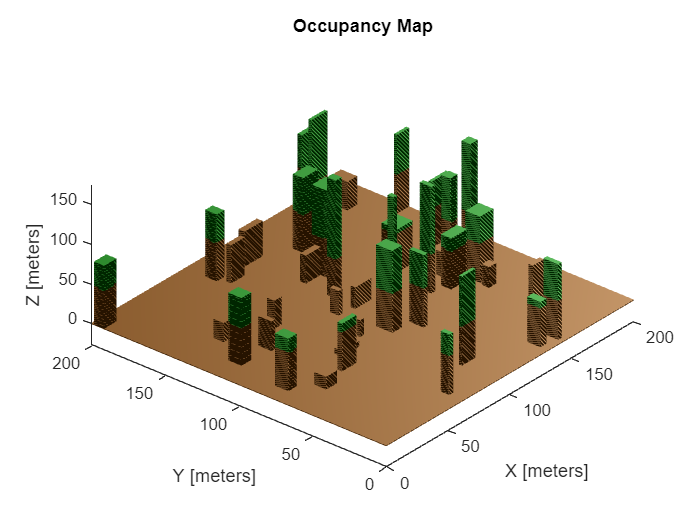

figure("Name","3D Mapa de ocupación")
show(omap)
colormap(gca, [0.5, 0.25, 0; 0, 0.5, 0; 0, 0.5, 0]); % estos colores simulan un bosque 

Lo descargo por si quiero utilizarlo en otro fichero:

save('bosque.mat', 'omap');

# Planificación de movimiento con RRT para UAV de ala fija

En el ejemplo anterior se observó cómo evitar obstáculos utilizando un multirrotor. En este caso, se dispone de un dron de ala fija que va a sobrevolar un bosque con árboles altos, utilizando el algoritmo Rapidly Exploring Random Tree (RRT), que se utiliza para encontrar una trayectoria factible desde una posición inicial hacia una posición objetivo en un mapa tridimensional. El algoritmo busca expandir el árbol de manera aleatoria y explorar nuevas regiones del espacio de búsqueda, creando una estructura que conecta la posición inicial con la posición objetivo

Un UAV de ala fija es de naturaleza no holonómica y debe cumplir con restricciones aerodinámicas como el ángulo de balanceo máximo, el ángulo de inclinación de vuelo y la velocidad del aire al moverse entre puntos de referencia.

mapData = load("bosque.mat","omap");
omap = mapData.omap;
% Se consideran los espacios desconocidos como desocupados
omap.FreeThreshold = omap.OccupiedThreshold;

Dando las posiciones iniciales y objetivo, se planifica una ruta con RRT, utilizando primitivas del movimiento del vehículo de Dubins en 3D, con las que se va a simular el vuelo. Utilizando el mapa anterior como referencia, se seleccionan las poses del dron de inicio y fin.

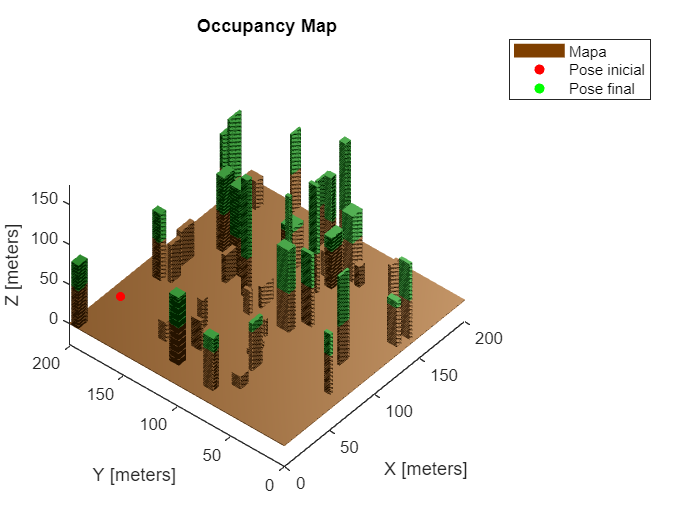

startPose = [20 170 40 pi/2];
goalPose = [170 30 40 pi/2];
figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
colormap(gca, [0.5, 0.25, 0; 0, 0.5, 0; 0, 0.5, 0]);
legend("Mapa","Pose inicial", "Pose final")
hold off

## Planificar una ruta con RRT utilizando primitivas de movimiento de Dubins

Se va a conectar las dos posiciones anteriores utilizando un objeto `uavDubinsConnection` que cumpla con las restricciones aerodinámicas. 

En primer lugar, se define el espacio de estados utilizando una implementación para la planificación de rutas encontrada en MathWorks. El espacio de estados se define como [x y z ángulo], donde (x,y,z) es la posición y el ángulo es el de orientación o yaw. Se especifica el ángulo de inclinación máxima, la velocidad del aire y el rango permitido de valores para el ángulo de trayectoria con respecto al plano horizontal (sirve para controlar los cambios de altitud). `Bounds `define los límites de posición y orientación del UAV en forma de una matriz 4x2. Las primeras tres filas representan los límites en los ejes x, y, z dentro del mapa de ocupación tridimensional, y la última fila representa el límite del ángulo de orientación.

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds", [-200 200; -200 200; 0 150; -pi pi]);

Ahora, se establecen los límites de umbral de la pose objetivo deseada, para marcar una región objetivo alrededor de la pose objetivo, en la que se considera que se ha tenido éxito.

threshold = [(goalPose-0.5)' (goalPose+0.5)'; -pi pi];

% se actualiza la región objetivo
setWorkspaceGoalRegion(ss,goalPose,threshold)

Se utiliza el objeto `validatorOccupancyMap3D` para evitar colisiones entre el UAV y el entorno. Un movimiento entre dos estados es válido sólo si todos los estados intermedios son válidos, por lo que el UAV no pasa por ningún lugar ocupado en el mapa.

Se observa que se infla el mapa 0.01 para asegurar que se eviten colisiones. 

sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.01;

### Planificador de trayectoria RRT

Se crea un objeto `plannerRRT` especificando el espacio de estados y el validador anterior. 

`planner.MaxConnectionDistance `establece la distancia máxima permitida para establecer conexiones entre estados vecinos durante la expansión del árbol RRT. 

`planner.GoalBias `define el sesgo de objetivo, que controla la dirección de muestreo hacia el objetivo durante la expansión del árbol. Esto quiere decir que se aumenta la probabilidad de que las muestras aleatorias se generen cerca del objetivo, lo que acelera el proceso de búsqueda, aumentando las posibilidades de encontrar una trayectoria hacia el objetivo de manera más eficiente.

`planner.MaxIterations `establece el número máximo de iteraciones permitidas para la construcción del árbol RRT. 

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 50;
planner.GoalBias = 0.10;  
planner.MaxIterations = 400;

Se ejecuta la planificación:

[pthObj,solnInfo] = plan(planner,startPose,goalPose);

Para simular el vuelo del dron siguiendo esta ruta, se utiliza la función auxiliar proporcionada en MathWorks, exampleHelperSimulateUAV, que requiere los puntos de referencia, la velocidad del aire y el tiempo para alcanzar el objetivo. Esta utiliza el modelo de guía de ala fija para simular el comportamiento del UAV basado en las entradas de control generadas a partir de los puntos de referencia. 

Observa que el vuelo simulado del UAV se desvía ligeramente de la ruta planificada debido a pequeños errores de seguimiento del control. Además, la trayectoria de Dubins en 3D asume cambios instantáneos en el ángulo de inclinación del UAV, pero la dinámica real tiene una respuesta más lenta a las órdenes de inclinación. Una forma de compensar este retraso es planificar rutas con restricciones aerodinámicas más conservadoras.

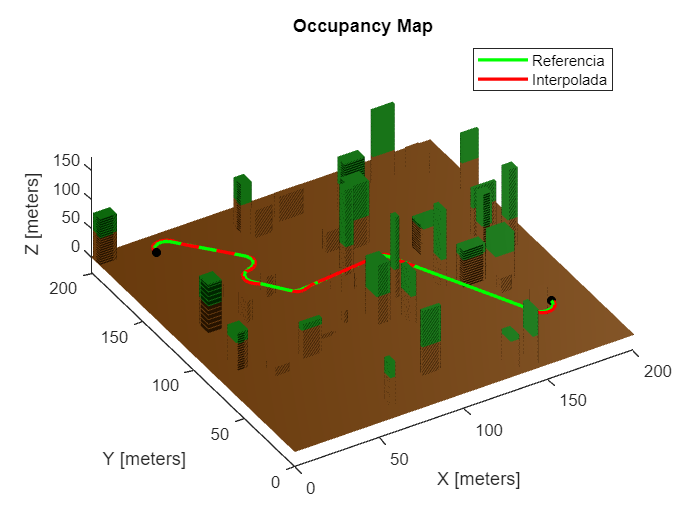

Se ha tardado en llegar a la posición objetivo 46.5307 segundos


% Si se ha encontrado una ruta válida
if (solnInfo.IsPathFound)
    % se crea una nueva figura en la que se representa el mapa con los
    % puntos anteriores
    figure("Name","OriginalPath")
    show(omap)
    colormap(gca, [0.5, 0.25, 0; 0, 0.5, 0; 0, 0.5, 0]);
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"black","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"black","filled")
    
    % se crea una copia de la ruta encontrada y la interpola de forma más
    % suave con 1000 puntos
    interpolatedPathObj = copy(pthObj);
    interpolate(interpolatedPathObj,1000)
    
    
    hReference = plot3(interpolatedPathObj.States(:,1), ...
        interpolatedPathObj.States(:,2), ...
        interpolatedPathObj.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    % se calcula el tiempo total de vuelo 
    timeToReachGoal = 1.05*pathLength(pthObj)/ss.AirSpeed;
    waypoints = interpolatedPathObj.States;

    % simula el vuelo del UAV y lo representa
    [xENU,yENU,zENU] = exampleHelperSimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    legend([hReference,hSimulated],"Referencia","Interpolada","Location","best")
    hold off

    % se ajusta la vista de la figura para una mejor visualización
    view([-31 63])

    % como se trata de una simulación, se multiplica por 1.05 Se multiplica por 1.05 para tener en cuenta un margen adicional del 
    % 5% en el tiempo estimado.
    timeToReachGoal = 1.05 * pathLength(pthObj) / ss.AirSpeed;
    disp("Se ha tardado en llegar a la posición objetivo " + timeToReachGoal + " segundos")

 else
    disp("No se ha encontrado una ruta válida");

end

En MathWorks también está disponible un algoritmo de suavizado de trayectoria, exampleHelperUAVPathSmoothing. Esta función elimina poses intermedias de Dubins en 3D basándose en una estrategia iterativa, de modo que se conectan poses de Dubins en 3D no secuenciales entre sí siempre que esto no resulte en colisión. De este modo, se simplifica la trayectoria y se mejoran las características de seguimiento.

Se aplica dicho algoritmo y se compara la trayectoria obtenida con la anterior.

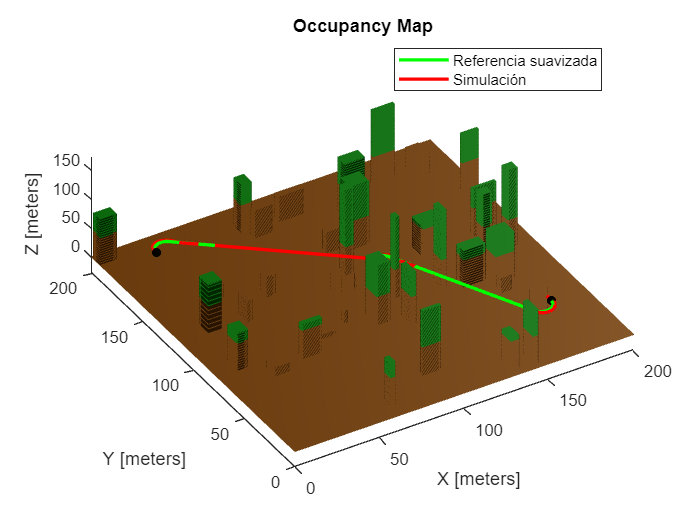

Se ha tardado en llegar a la posición objetivo 40.7016 segundos


if (solnInfo.IsPathFound)
    smoothWaypointsObj = exampleHelperUAVPathSmoothing(ss,sv,pthObj);
    
    figure("Name","SmoothedPath")
    show(omap)
    colormap(gca, [0.5, 0.25, 0; 0, 0.5, 0; 0, 0.5, 0]);
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"black","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"black","filled")
    
    interpolatedSmoothWaypoints = copy(smoothWaypointsObj);
    interpolate(interpolatedSmoothWaypoints,1000)
    
    hReference = plot3(interpolatedSmoothWaypoints.States(:,1), ...
        interpolatedSmoothWaypoints.States(:,2), ...
        interpolatedSmoothWaypoints.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    waypoints = interpolatedSmoothWaypoints.States;
    timeToReachGoal = 1.05*pathLength(smoothWaypointsObj)/ss.AirSpeed;
    [xENU,yENU,zENU] = exampleHelperSimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    
    legend([hReference,hSimulated],"Referencia suavizada","Simulación","Location","best")
    hold off
    view([-31 63]);

    % como se trata de una simulación, se multiplica por 1.05 Se multiplica por 1.05 para tener en cuenta un margen adicional del 
    % 5% en el tiempo estimado.
    timeToReachGoal = 1.05 * pathLength(smoothWaypointsObj) / ss.AirSpeed;
    disp("Se ha tardado en llegar a la posición objetivo " + timeToReachGoal + " segundos")

    else
    disp("No se ha encontrado una ruta válida");
end

Como se puede observar, el suavizado acorta el tiempo de vuelo del dron. 

Ahora, utilizando las funciones de `writeVideo` (https://es.mathworks.com/help/matlab/ref/videowriter.writevideo.html), se puede generar un vídeo de una simulación de un dron (en este caso, un punto celeste) que recorre la trayectoria generada.

videoFilename = 'simulacion_dron4.mp4';

% Crear un objeto VideoWriter
videoWriter = VideoWriter(videoFilename, 'MPEG-4');

% Establecer la velocidad de cuadro por segundo
frameRate = 40;  

videoWriter.FrameRate = frameRate;
open(videoWriter);

% Configurar la figura y el bucle de animación
figure("Name","Simulación de trayectorias")
hold on

% Visualizar el mapa de ocupación y la trayectoria obtenida
show(omap)
colormap(gca, [0.5, 0.25, 0; 0, 0.5, 0; 0, 0.5, 0]);

hReference = plot3(interpolatedSmoothWaypoints.States(:,1), ...
    interpolatedSmoothWaypoints.States(:,2), ...
    interpolatedSmoothWaypoints.States(:,3), ...
    "LineWidth",2,"Color","g");

% Visualizar puntos de inicio y objetivo
scatter3(startPose(1),startPose(2),startPose(3),30,"black","filled")
scatter3(goalPose(1),goalPose(2),goalPose(3),30,"black","filled")

% Inicializar la posición del dron en la posición inicial
dronePosition = [startPose(1), startPose(2), startPose(3)];

% Visualizar el dron en la posición inicial
hDrone = scatter3(dronePosition(1), dronePosition(2), dronePosition(3), 'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75]);

% Simulación del movimiento del dron y grabación de fotogramas
for i = 1:size(waypoints, 1)
    % Actualizar la posición del dron
    dronePosition = waypoints(i, :);

    % Actualizar la visualización del dron
    set(hDrone, 'XData', dronePosition(1), 'YData', dronePosition(2), 'ZData', dronePosition(3));

    % Actualizar la figura
    drawnow;

    % Grabar el cuadro actual en el archivo de video
    frame = getframe(gcf);
    writeVideo(videoWriter, frame);
end

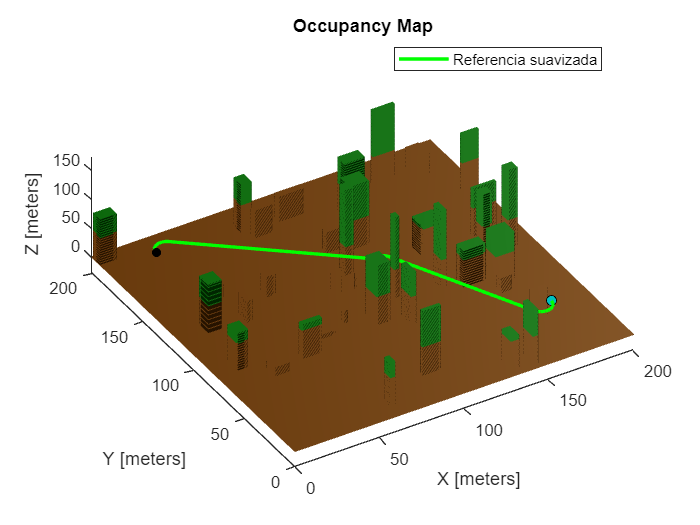

close(videoWriter);

legend(hReference,"Referencia suavizada","Location","best")
hold off
view([-31 63]);